% H_infinity weight optimisers 
clf

s = tf('s');  % Laplace variable


upper_bound = 100 / (s/10 + 1); % TRIAL 1: THIS AND LB_2ND_ORDER WORKS
% upper_bound = (700 * (s/2 + 1)^4) / ((s/0.2 + 1)^5 * (s/200 + 1)^5);
% lower_bound = (500 * (s/0.3 + 1)) / ((s/0.03 + 1)^2 * (s/30 + 1)^7);
% A1 = 1/100;
% wBS1 = 10;
% M1 = 0.5;
% wS1=((s/M1+wBS1)/(s+wBS1*A1))^2;
% %complementary sensitivity function
% A2 = 1/1000;
% wBS2 = 1000;
% M2 = 0.5;
% wS3=((s/M2+wBS1)/(s+wBS2*A2))^2;
% %Control sensitivty 
% wS2=1;

% lower_bound = 0.1/(s+5);
% lower_bound = 0.1 * (s + 1)/(s*(s/100 + 1)); 
% 
K_lp = 0.1;
omega_n = 5;
zeta = 0.9;  % damping ratio
lower_bound= K_lp * omega_n^2 / (s^2 + 2*zeta * omega_n * s + omega_n^2)


lower_bound =
 
       2.5
  --------------
  s^2 + 9 s + 25
 
Continuous-time transfer function.
Model Properties


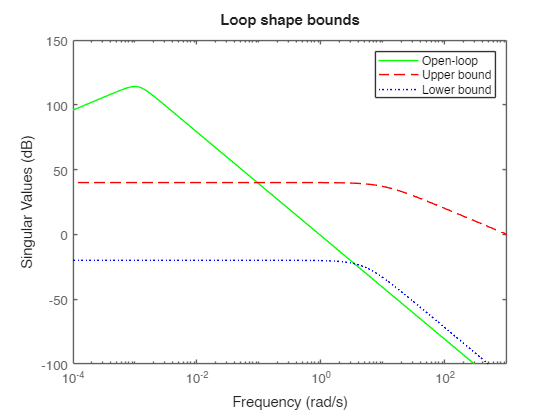



bounds = [upper_bound; lower_bound];
% 
% hold off
% sigma(P_pitch, 'g', upper_bound, 'r--', lower_bound, 'b:');
% title("Loop shape bounds")
% legend("Open-loop", "Upper bound", "Lower bound")


% 
% hold off
% sigma(P_roll_cyc, 'g', wS1, 'r--', wS3, 'b:');
% title("Loop shape bounds")
% legend("Open-loop", "Upper bound", "Lower bound")

% [emax_pitch, W1_pitch, W2_pitch, Cinf_pitch] = optimise_compensators(heli_ss_lon, bounds)

